# 普通广角/鱼眼镜头径向去畸变——除法模型动态调整实时求解

崔星星 2023.5.15

Email: cuixingxing150@gmail.com

为了解决对**单张畸变图像中存在空间“直线”较少(比如畸变图像中很难找到超过3条或者干脆没有)的情况下较难估计畸变中心+畸变系数问题**，故设计以下程序用于动态调节单个畸变系数就可直观查看去畸变图像效果，方便快捷，此工具真香~

对于除法模型中的畸变系数只取一项就足以满足绝大数场合[1，2],其优势比传统上的多项式畸变模型有很多，在此不具体展开，具体可以参考文后的References[1，2]。特别地，当其为负值时，畸变图像表现为“桶形”；为正值时，表现为“枕形”；为0时，表现为无畸变。故设计使用下面交互程序时需要人为初步估计这个系数$\lambda$（一般"桶形"畸变图像取$-{10}^{-6} ~{-10}^{-7}$数量级之间），然后设定好合适的变动范围，边手动拖动滑块调节边可以查看到去畸变图像的实时效果。

## 读入原始畸变图像

distortionImage = imread("./images/distortedImageDemo.jpg");
[H,W,~] = size(distortionImage);

## 设计动态调节的参数去畸变

动态调节的参数共设计为$\left(x_c ,y_c ,\lambda \right)$三个，其中畸变中心$\left(x_c ,y_c \right)$一般位于图像几何中心附近。

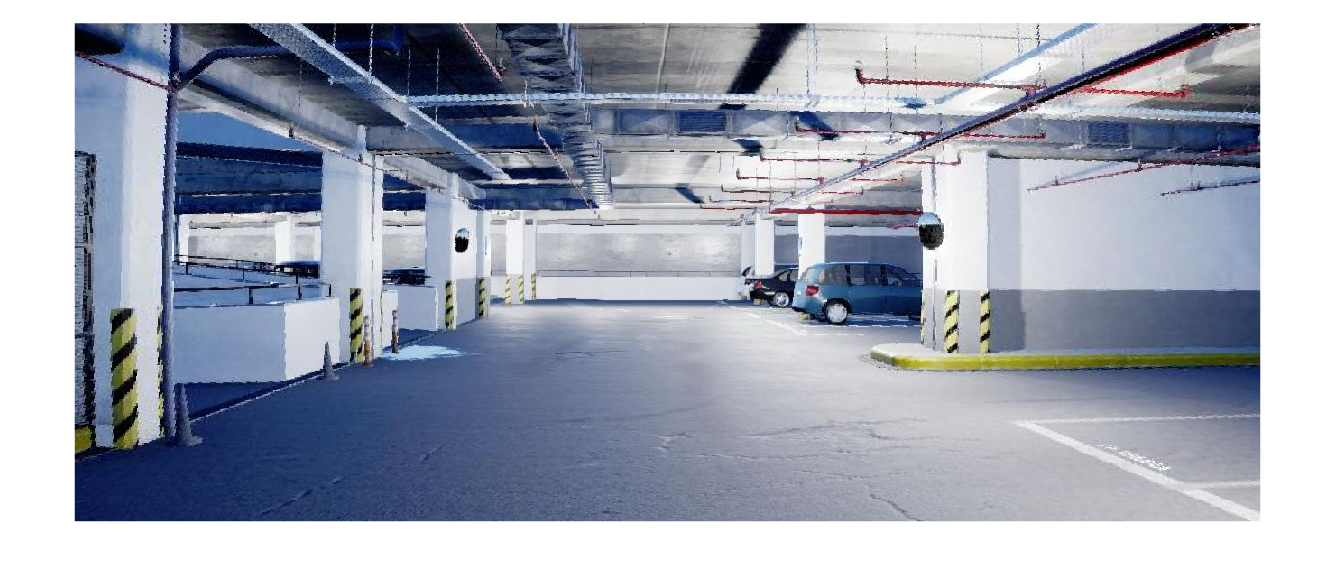

% x_center 滑块设计
minX = W/4;
maxX = 3*W/4;
stepX = (maxX-minX)/50;
defaultX = W/2+0.5;
x_center = 435.61;

% y_center 滑块设计
minY = H/4;
maxY = 3*H/4;
stepY = (maxY-minY)/50;
defaultY = H/2+0.5;
y_center = 243.53;

% lambda 滑块设计
minV = -3.6*10^(-6);
maxV = -1*10^(-7);
stepV = (maxV-minV)/100;
defaultV = -2*10^(-7);
lambda = -0.00000164;
% lambda = minV;
undistortImage = undistortImageForDivisionModel(distortionImage,lambda,x_center,y_center,OutputView="valid");

imshow(undistortImage)

## References:

[1] [https://wiki2.org/en/Distortion_(optics)](https://wiki2.org/en/Distortion_(optics))

[2] Wang, A., Qiu, T., Shao, L.: A simple method of radial distortion correction with centre of distortion estimation. Journal of Mathematical Imaging and Vision 35 (2009) 165–172